## eVTOL Multiobjective Design Optimization

# VERSION: MDO_MOO_Model_v5_080824

Master's Research Project 

Author: Johannes Janning 

## Intro

% Clearing the workspace and the command window 
clc
clear

% Importing the model functions
addpath('/Users/johannes/Dropbox/Mein Mac (Johanness MacBook Pro (2))/Documents/MATLAB/Master_Project//MDO_MOO_Model_v5_080824/Model_Functions/Aerodynamics_Model/');
addpath('/Users/johannes/Dropbox/Mein Mac (Johanness MacBook Pro (2))/Documents/MATLAB/Master_Project//MDO_MOO_Model_v5_080824/Model_Functions/PowerMT_Model/');
addpath('/Users/johannes/Dropbox/Mein Mac (Johanness MacBook Pro (2))/Documents/MATLAB/Master_Project//MDO_MOO_Model_v5_080824/Model_Functions/Time_Model/');
addpath('/Users/johannes/Dropbox/Mein Mac (Johanness MacBook Pro (2))/Documents/MATLAB/Master_Project//MDO_MOO_Model_v5_080824/Model_Functions/Energy_Model/');
addpath('/Users/johannes/Dropbox/Mein Mac (Johanness MacBook Pro (2))/Documents/MATLAB/Master_Project//MDO_MOO_Model_v5_080824/Model_Functions/Weight_Model/');
addpath('/Users/johannes/Dropbox/Mein Mac (Johanness MacBook Pro (2))/Documents/MATLAB/Master_Project//MDO_MOO_Model_v5_080824/Model_Functions/Cost_Model/Cash Operating Costs/');
addpath('/Users/johannes/Dropbox/Mein Mac (Johanness MacBook Pro (2))/Documents/MATLAB/Master_Project//MDO_MOO_Model_v5_080824/Model_Functions/Cost_Model//Cost of Ownership and IOC/');
addpath('/Users/johannes/Dropbox/Mein Mac (Johanness MacBook Pro (2))/Documents/MATLAB/Master_Project//MDO_MOO_Model_v5_080824/Model_Functions/Cost_Model//Total Operating Costs/');
addpath('/Users/johannes/Dropbox/Mein Mac (Johanness MacBook Pro (2))/Documents/MATLAB/Master_Project//MDO_MOO_Model_v5_080824/Optimization/');

## Setting fixed simulation paramaters

% Trip distance as separate selectable fixed variable 
set_trip_distance = 70; % km
params = getFixedParameters1(); % FUNCTION calling the fixed paramaters, predefined based on literature research (see model documentation)

params = struct with fields:
                   g: 9.8100
            h_tofldg: 0
             h_hover: 15.2400
            h_cruise: 1.2192e+03
           rho_hover: 1.2250
                 rho: 1.0879
           rho_climb: 1.1549
             rho_msl: 1.2250
    alpha_deg_cruise: 3
     alpha_deg_climb: 8
       alpha_deg_max: 15
    num_props_cruise: 1
     num_props_hover: 8
               d_tip: 0.0250
          w_fuselage: 1.5000
             l_fus_m: 6
             r_fus_m: 0.7500
               M_pax: 82
               M_lug: 16
              m_crew: 96.5000
             m_other: 668
     m_motor_initial: 500
       m_bat_initial: 200
             rho_bat: 400
            C_charge: 1
                 N_s: 4
           P_s_empty: 1.4365e+03
                N_wd: 260
                N_df: 6
                 P_e: 0.0967
             P_bat_s: 115
               t_res: 1800
             t_hover: 60
                 T_D: 28800
                 S_P: 45400
                N_AC: 1
     

## Definition of bounds

% Define the bounds of the optimized design variables
bounds = [500, 5700; % MTOM
          1, 2;  % R_cruise
          1, 2;  % R_hover
          1.3, 4;  % c
          8, 40;] % b

bounds = 1.0e+03 *

    0.5000    5.7000
    0.0010    0.0020
    0.0010    0.0020
    0.0013    0.0040
    0.0080    0.0400


## Initialization of GA for multiobjective Optimization

% GA options using ga for multiobjective
options = optimoptions('gamultiobj', 'PopulationSize', 100, 'Display', 'iter');


% to run the multi-objective GA
[x, fval, exitFlag, output, population, scores] = gamultiobj(@(x)multiObjectiveFunction1(x, params, set_trip_distance), 5, [], [], [], [], bounds(:,1), bounds(:,2), @(x)nonlinearConstraints1(x, params, set_trip_distance), options);


Multi-objective optimization:
5 Variables
2 Nonlinear inequality constraints

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverintermediate
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationadaptfeasible

                              Average            Average
Generation   Func-count    Pareto distance    Pareto spread
    1           101                 1                 1
    2           201          0.376647          0.999825
    3           301          0.314658          0.709987
    4           401          0.215946          0.990081
    5           501          0.110619          0.999948
    6           601           0.19375          0.999809
    7           701          0.165227          0.999945
    8           801          0.174542          0.609299
    9           901           0.15267          0.996115
   10          1001          0.138479          0.999821
   11          1101          0.106164          0.998535
   12          1


% to display results
disp('Optimized Design Variables (x):');

Optimized Design Variables (x):


disp(x);

   1.0e+03 *

    5.6134    0.0013    0.0013    0.0013    0.0094
    1.8988    0.0020    0.0015    0.0013    0.0243
    3.9640    0.0016    0.0013    0.0013    0.0094
    2.1992    0.0019    0.0014    0.0013    0.0116
    1.9030    0.0020    0.0015    0.0013    0.0201
    3.7200    0.0017    0.0013    0.0013    0.0096
    1.9821    0.0019    0.0014    0.0013    0.0150
    2.0404    0.0019    0.0014    0.0013    0.0139
    1.9011    0.0020    0.0015    0.0013    0.0230
    3.0137    0.0016    0.0013    0.0013    0.0097
    1.9027    0.0020    0.0015    0.0013    0.0216
    1.9135    0.0018    0.0014    0.0013    0.0158
    2.1072    0.0018    0.0014    0.0013    0.0136
    4.8584    0.0014    0.0013    0.0013    0.0094
    3.4586    0.0018    0.0013    0.0013    0.0097
    2.4312    0.0018    0.0013    0.0013    0.0105
    2.0857    0.0019    0.0013    0.0013    0.0123
    5.5770    0.0017    0.0013    0.0013    0.0095
    2.5646    0.0017    0.0013    0.0013    0.0100
    5.6134    0.0

disp('Objective Values:');

Objective Values:


disp(fval);

   1.0e+05 *

    2.4707    0.0062
    0.6430    0.0168
    1.6512    0.0072
    0.8327    0.0106
    0.6559    0.0152
    1.5241    0.0075
    0.7113    0.0128
    0.7448    0.0121
    0.6468    0.0163
    1.2285    0.0084
    0.6512    0.0158
    0.6882    0.0134
    0.7799    0.0118
    2.0854    0.0066
    1.4047    0.0078
    0.9535    0.0096
    0.7807    0.0113
    2.3565    0.0062
    1.0212    0.0091
    2.4707    0.0062
    0.6685    0.0141
    2.4260    0.0062
    2.1581    0.0065
    2.3079    0.0063
    0.8180    0.0110
    1.8784    0.0069
    1.3322    0.0079
    1.1748    0.0084
    1.9943    0.0067
    1.1309    0.0087
    1.7598    0.0070
    1.7361    0.0071
    1.8998    0.0068
    1.6039    0.0075
    0.8958    0.0102



## Post-Processing (MTOM check) & Transportation Mode Comparison Processing

% function to process optimization results for illustration
results = processOptimizationResults1(x, fval, params, set_trip_distance);

## Results and Pareto-Front Displaying


% Defining the names of the objectives, design variables, and calculated values
objectiveNames = {'Trip_Energy [Wh]', 'Trip_Time [sec]'};
designVarNames = {'MTOM [kg]', 'R_cruise [m]', 'R_hover [m]', 'chord [m]', 'wingspan_b [m]'};
calculatedVarNames = {'rho_bat [Wh/kg]', 'V_cruise [m/s]', 'V_climb [m/s]', 'Power_hover [W]', 'Power_climb [W]', 'Power_cruise [W]', 'E_battery [kWh]', 'EpK [kWh/km]', 'm_empty [kg]', 'm_pay [kg]', 'm_bat [kg]', 'm_motor [kg]', 'm_rotor [kg]', 'm_wing [kg]', 'm_gear [kg]', 'm_furnish [kg]', 'm_fuselage [kg]', 'm_system [kg]', 'c_l_cruise [-]', 'c_l_climb [-]', 'c_d_cruise [-]', 'c_d_climb [-]', 'LD_cruise [-]', 'LD_climb [-]', 'ROC [ft/min]', 'Aspect Ratio [-]', 'Wing Loading [kg/m^2]', 'Disk Loading [kg/m^2]', 'TOC_skm [€/skm]', 'TOC [€]', 'DOC [€]', 'COC [€]', 'C_energy [€]', 'C_m [€]', 'C_mwr [€]', 'C_mb [€]', 'C_nav [€]', 'C_crew [€]', 'COO [€]', 'IOC [€]', 'AC_cost_unit [€]', 'ECE [€/kWh]', 'BCE [€/kWh]', 'n_bat_req_a [-]', 'n_bat_cycles [-]', 'DOD [%/100]', 'C_rate_hover [1/h]', 'C_rate_climb [1/h]', 'C_rate_cruise [1/h]', 'C_rate_average [1/h]', 'C_charge [1/h]', 'T_T [sec]', 'DH [-]', 'P_bat_single [€]', 'P_bat_annual [€]', 'GWP_flight [CO2e kg]', 'GWP_annual [CO2e kg]', 'GWPpK [CO2e kg/km]', 'CEE [CO2e kg/kWh]', 'GWP_trip_energy_fraction [-]', 'CSI [€*kgCO2e/km]', 'COI [-]', 'FC_a [-]', 'FC_d [-]', 'FH_a [hrs]', 'FH_d [hrs]', 'Profit_annual [€]', 'Profit_flight [€]', 'PR [-]', 'RpK [€/km]', 'ticket_price_pax [€]', 'd_cru [m]', 'd_cl [m]', 'eVTOL_FoM [-]'};

% Creating a table for the results with custom names
resultsTable = array2table(results, 'VariableNames', [objectiveNames, designVarNames, calculatedVarNames]);

% Sorting the table by the first objective function (change the index to sort by a different objective)
sortedResultsTable = sortrows(resultsTable, 'Trip_Energy [Wh]');

% to display the sorted table
disp('Sorted Results Table:');

Sorted Results Table:


disp(sortedResultsTable);

    Trip_Energy [Wh]    Trip_Time [sec]    MTOM [kg]    R_cruise [m]    R_hover [m]    chord [m]    wingspan_b [m]    rho_bat [Wh/kg]    V_cruise [m/s]    V_climb [m/s]    Power_hover [W]    Power_climb [W]    Power_cruise [W]    E_battery [kWh]    EpK [kWh/km]    m_empty [kg]    m_pay [kg]    m_bat [kg]    m_motor [kg]    m_rotor [kg]    m_wing [kg]    m_gear [kg]    m_furnish [kg]    m_fuselage [kg]    m_system [kg]    c_l_cruise [-]    c_l_climb [-]    c_d_cruise [-]    c_d_climb [-]    LD_c





%%%% SINGLE LINES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%




% Find the row index of the minimum Trip Energy value
[~, minEIndex] = min(sortedResultsTable{:, 'Trip_Energy [Wh]'});
minERow = sortedResultsTable(minEIndex, :);
disp('Row with the Lowest Trip Energy:');

Row with the Lowest Trip Energy:


disp(minERow);

    Trip_Energy [Wh]    Trip_Time [sec]    MTOM [kg]    R_cruise [m]    R_hover [m]    chord [m]    wingspan_b [m]    rho_bat [Wh/kg]    V_cruise [m/s]    V_climb [m/s]    Power_hover [W]    Power_climb [W]    Power_cruise [W]    E_battery [kWh]    EpK [kWh/km]    m_empty [kg]    m_pay [kg]    m_bat [kg]    m_motor [kg]    m_rotor [kg]    m_wing [kg]    m_gear [kg]    m_furnish [kg]    m_fuselage [kg]    m_system [kg]    c_l_cruise [-]    c_l_climb [-]    c_d_cruise [-]    c_d_climb [-]    LD_c


% Find the row index of the minimum GWP per flight value
[~, minGWPFIndex] = min(sortedResultsTable{:, 'GWP_flight [CO2e kg]'});
minGWPFRow = sortedResultsTable(minGWPFIndex, :);
disp('Row with the lowest GWP per flight:');

Row with the lowest GWP per flight:


disp(minGWPFRow);

    Trip_Energy [Wh]    Trip_Time [sec]    MTOM [kg]    R_cruise [m]    R_hover [m]    chord [m]    wingspan_b [m]    rho_bat [Wh/kg]    V_cruise [m/s]    V_climb [m/s]    Power_hover [W]    Power_climb [W]    Power_cruise [W]    E_battery [kWh]    EpK [kWh/km]    m_empty [kg]    m_pay [kg]    m_bat [kg]    m_motor [kg]    m_rotor [kg]    m_wing [kg]    m_gear [kg]    m_furnish [kg]    m_fuselage [kg]    m_system [kg]    c_l_cruise [-]    c_l_climb [-]    c_d_cruise [-]    c_d_climb [-]    LD_c


% Find the row index of the minimum GWP annual value
[~, minGWPaIndex] = min(sortedResultsTable{:, 'GWP_annual [CO2e kg]'});
minGWPaRow = sortedResultsTable(minGWPaIndex, :);
disp('Row with the lowest annual GWP:');

Row with the lowest annual GWP:


disp(minGWPaRow);

    Trip_Energy [Wh]    Trip_Time [sec]    MTOM [kg]    R_cruise [m]    R_hover [m]    chord [m]    wingspan_b [m]    rho_bat [Wh/kg]    V_cruise [m/s]    V_climb [m/s]    Power_hover [W]    Power_climb [W]    Power_cruise [W]    E_battery [kWh]    EpK [kWh/km]    m_empty [kg]    m_pay [kg]    m_bat [kg]    m_motor [kg]    m_rotor [kg]    m_wing [kg]    m_gear [kg]    m_furnish [kg]    m_fuselage [kg]    m_system [kg]    c_l_cruise [-]    c_l_climb [-]    c_d_cruise [-]    c_d_climb [-]    LD_c


% Find the row index of the minimum TOC value
[~, minTocIndex] = min(sortedResultsTable{:, 'TOC [€]'});
minTocRow = sortedResultsTable(minTocIndex, :);
disp('Row with the Lowest Total Operating Cost:');

Row with the Lowest Total Operating Cost:


disp(minTocRow);

    Trip_Energy [Wh]    Trip_Time [sec]    MTOM [kg]    R_cruise [m]    R_hover [m]    chord [m]    wingspan_b [m]    rho_bat [Wh/kg]    V_cruise [m/s]    V_climb [m/s]    Power_hover [W]    Power_climb [W]    Power_cruise [W]    E_battery [kWh]    EpK [kWh/km]    m_empty [kg]    m_pay [kg]    m_bat [kg]    m_motor [kg]    m_rotor [kg]    m_wing [kg]    m_gear [kg]    m_furnish [kg]    m_fuselage [kg]    m_system [kg]    c_l_cruise [-]    c_l_climb [-]    c_d_cruise [-]    c_d_climb [-]    LD_c


% Find the row index of the max Profit per flight value
[~, maxProfitFIndex] = max(sortedResultsTable{:, 'Profit_flight [€]'});
maxProfitFRow = sortedResultsTable(maxProfitFIndex, :);
disp('Row with the highest Profit per flight:');

Row with the highest Profit per flight:


disp(maxProfitFRow);

    Trip_Energy [Wh]    Trip_Time [sec]    MTOM [kg]    R_cruise [m]    R_hover [m]    chord [m]    wingspan_b [m]    rho_bat [Wh/kg]    V_cruise [m/s]    V_climb [m/s]    Power_hover [W]    Power_climb [W]    Power_cruise [W]    E_battery [kWh]    EpK [kWh/km]    m_empty [kg]    m_pay [kg]    m_bat [kg]    m_motor [kg]    m_rotor [kg]    m_wing [kg]    m_gear [kg]    m_furnish [kg]    m_fuselage [kg]    m_system [kg]    c_l_cruise [-]    c_l_climb [-]    c_d_cruise [-]    c_d_climb [-]    LD_c


% Find the row index of the max profit annual value
[~, maxProfitaIndex] = max(sortedResultsTable{:, 'Profit_annual [€]'});
maxProfitaRow = sortedResultsTable(maxProfitaIndex, :);
disp('Row with the highest annual Profit:');

Row with the highest annual Profit:


disp(maxProfitaRow);

    Trip_Energy [Wh]    Trip_Time [sec]    MTOM [kg]    R_cruise [m]    R_hover [m]    chord [m]    wingspan_b [m]    rho_bat [Wh/kg]    V_cruise [m/s]    V_climb [m/s]    Power_hover [W]    Power_climb [W]    Power_cruise [W]    E_battery [kWh]    EpK [kWh/km]    m_empty [kg]    m_pay [kg]    m_bat [kg]    m_motor [kg]    m_rotor [kg]    m_wing [kg]    m_gear [kg]    m_furnish [kg]    m_fuselage [kg]    m_system [kg]    c_l_cruise [-]    c_l_climb [-]    c_d_cruise [-]    c_d_climb [-]    LD_c


% Find the row index of the max Transport FOM value
[~, maxFOMIndex] = max(sortedResultsTable{:, 'eVTOL_FoM [-]'});
maxFOMRow = sortedResultsTable(maxFOMIndex, :);
disp('Row with the highest Transportation FoM:');

Row with the highest Transportation FoM:


disp(maxFOMRow);

    Trip_Energy [Wh]    Trip_Time [sec]    MTOM [kg]    R_cruise [m]    R_hover [m]    chord [m]    wingspan_b [m]    rho_bat [Wh/kg]    V_cruise [m/s]    V_climb [m/s]    Power_hover [W]    Power_climb [W]    Power_cruise [W]    E_battery [kWh]    EpK [kWh/km]    m_empty [kg]    m_pay [kg]    m_bat [kg]    m_motor [kg]    m_rotor [kg]    m_wing [kg]    m_gear [kg]    m_furnish [kg]    m_fuselage [kg]    m_system [kg]    c_l_cruise [-]    c_l_climb [-]    c_d_cruise [-]    c_d_climb [-]    LD_c


% Filter the table to include only rows where COI is greater than 0
filteredTable = sortedResultsTable(sortedResultsTable{:,'COI [-]'} > 0, :);
[~, minCOIIndex] = min(filteredTable{:,'COI [-]'});
minCOIRow = filteredTable(minCOIIndex, :);
disp('Row with the lowest COI per Design (greater than 0):');

Row with the lowest COI per Design (greater than 0):


disp(minCOIRow);

    Trip_Energy [Wh]    Trip_Time [sec]    MTOM [kg]    R_cruise [m]    R_hover [m]    chord [m]    wingspan_b [m]    rho_bat [Wh/kg]    V_cruise [m/s]    V_climb [m/s]    Power_hover [W]    Power_climb [W]    Power_cruise [W]    E_battery [kWh]    EpK [kWh/km]    m_empty [kg]    m_pay [kg]    m_bat [kg]    m_motor [kg]    m_rotor [kg]    m_wing [kg]    m_gear [kg]    m_furnish [kg]    m_fuselage [kg]    m_system [kg]    c_l_cruise [-]    c_l_climb [-]    c_d_cruise [-]    c_d_climb [-]    LD_c


% Find the row index of the minimum CSI value
[~, minCSIIndex] = min(sortedResultsTable{:, 'CSI [€*kgCO2e/km]'});
minCSIRow = sortedResultsTable(minCSIIndex, :);
disp('Row with the lowest CSI per Design:');

Row with the lowest CSI per Design:


disp(minCSIRow);

    Trip_Energy [Wh]    Trip_Time [sec]    MTOM [kg]    R_cruise [m]    R_hover [m]    chord [m]    wingspan_b [m]    rho_bat [Wh/kg]    V_cruise [m/s]    V_climb [m/s]    Power_hover [W]    Power_climb [W]    Power_cruise [W]    E_battery [kWh]    EpK [kWh/km]    m_empty [kg]    m_pay [kg]    m_bat [kg]    m_motor [kg]    m_rotor [kg]    m_wing [kg]    m_gear [kg]    m_furnish [kg]    m_fuselage [kg]    m_system [kg]    c_l_cruise [-]    c_l_climb [-]    c_d_cruise [-]    c_d_climb [-]    LD_c




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%% extracting data in excel table 

% Saving the table to an Excel file
writetable(sortedResultsTable, 'sorted_results_v7.xlsx');


% Step 1: Generate a unique timestamp
timestamp = datestr(now, 'yyyymmdd_HHMMSS'); % Example: '20230815_153045'

% Step 2: Define the specific folder path where you want to save the files
savePath = '/Users/johannes/Dropbox/Mein Mac (Johanness MacBook Pro (2))/Documents/MATLAB/Master_Project/MDO_MOO_Model_v5_080824/Documentation/';

% Step 5: Generate a unique filename using the timestamp and combine it with the save path
filename = sprintf('%ssorted_results_%s.xlsx', savePath, timestamp);
% Step 6: Save the sorted table to the first sheet of the Excel file
writetable(sortedResultsTable, filename, 'Sheet', 'Sorted Results');
writetable(minERow, filename, 'Sheet', 'Min Trip Energy');
writetable(minTocRow, filename, 'Sheet', 'Min TOC');
writetable(minCOIRow, filename, 'Sheet', 'Min COI');

% Step 7: Save the sorted table to an Excel file in the specified folder
writetable(sortedResultsTable, filename);

% (Optional) Display the path and filename where the file is saved
disp(['Results saved to: ', filename]);

Results saved to: /Users/johannes/Dropbox/Mein Mac (Johanness MacBook Pro (2))/Documents/MATLAB/Master_Project/MDO_MOO_Model_v5_080824/Documentation/sorted_results_20240822_183711.xlsx


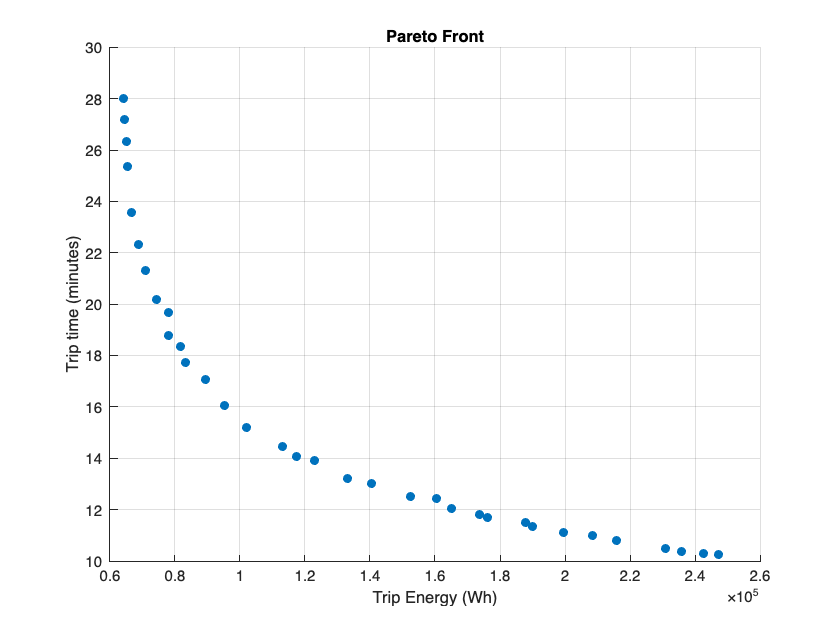



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Plotting the Pareto front
figure;
scatter(fval(:, 1), fval(:, 2)/60, 'filled');
title('Pareto Front');
xlabel('Trip Energy (Wh)');
ylabel('Trip time (minutes)');
grid on;

## Results Graph Displaying

% Ensuring that the 'toc' values are consistent with 'Trip_Energy', to
% prevent table mismatch 
toc_values = sortedResultsTable{:, 'TOC [€]'};
trip_energy = sortedResultsTable{:, 'Trip_Energy [Wh]'};
trip_time = sortedResultsTable{:, 'Trip_Time [sec]'};
Profit_annual = sortedResultsTable{:, 'Profit_annual [€]'};
COI_values = sortedResultsTable{:, 'COI [-]'}

COI_values =     0.0926
    0.0882
    0.0837
    0.0789
    0.0711
    0.0672
    0.0668
    0.0658
    0.0679
    0.0635


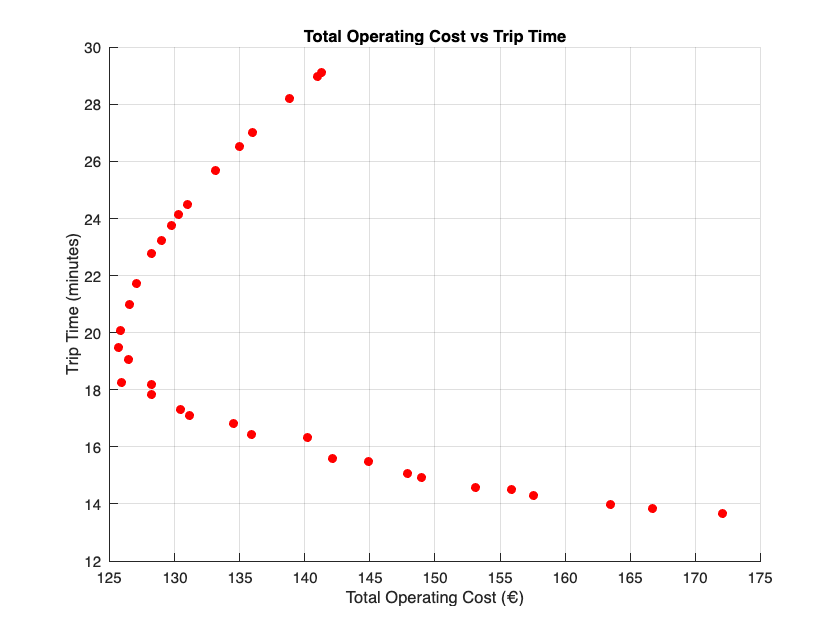


% Plotting TOC against Trip Time to verify consistency
figure;
scatter( toc_values, trip_time/60, 'filled', 'r');
title('Total Operating Cost vs Trip Time');
xlabel('Total Operating Cost (€)');
ylabel('Trip Time (minutes)');
grid on;

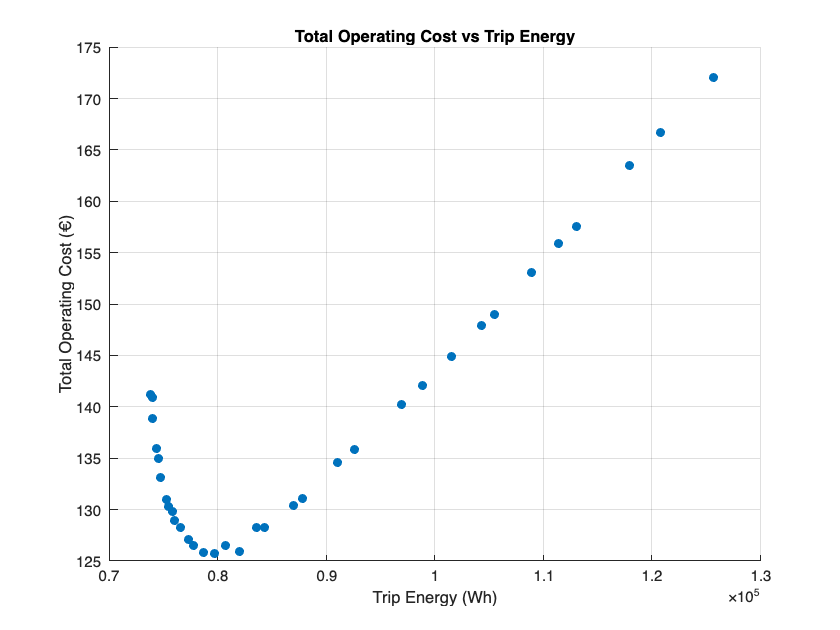


% Plotting TOC against Trip Energy
figure;
scatter(trip_energy, toc_values, 'filled');
title('Total Operating Cost vs Trip Energy');
xlabel('Trip Energy (Wh)');
ylabel('Total Operating Cost (€)');
grid on;





%%%%%% HEATMAP 

% Creating a meshgrid for trip_time and trip_energy
[TripTime, TripEnergy] = meshgrid(unique(trip_time), unique(trip_energy));

% Interpolating total operating cost (toc_values) over the meshgrid
TotalOperatingCost = griddata(trip_time, trip_energy, toc_values, TripTime, TripEnergy, 'linear');

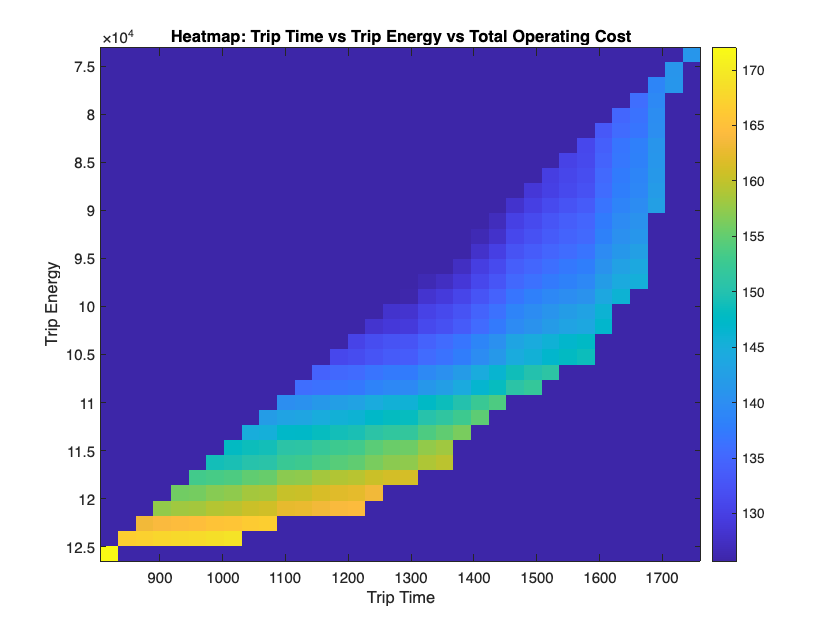


figure;
imagesc(TripTime(1,:), TripEnergy(:,1), TotalOperatingCost);
title('Heatmap: Trip Time vs Trip Energy vs Total Operating Cost');
xlabel('Trip Time');
ylabel('Trip Energy');
colorbar; % Adds a color bar to indicate cost levels




% Convert trip_time to minutes and sort in decreasing order
trip_time_minutes = sort(unique(trip_time / 60), 'descend');

% Creating a meshgrid for trip_energy and the adjusted trip_time
[TripEnergy, TripTime] = meshgrid(unique(trip_energy), trip_time_minutes);

% Interpolating total operating cost (toc_values) over the meshgrid
TotalOperatingCost = griddata(trip_energy, trip_time / 60, toc_values, TripEnergy, TripTime, 'linear');

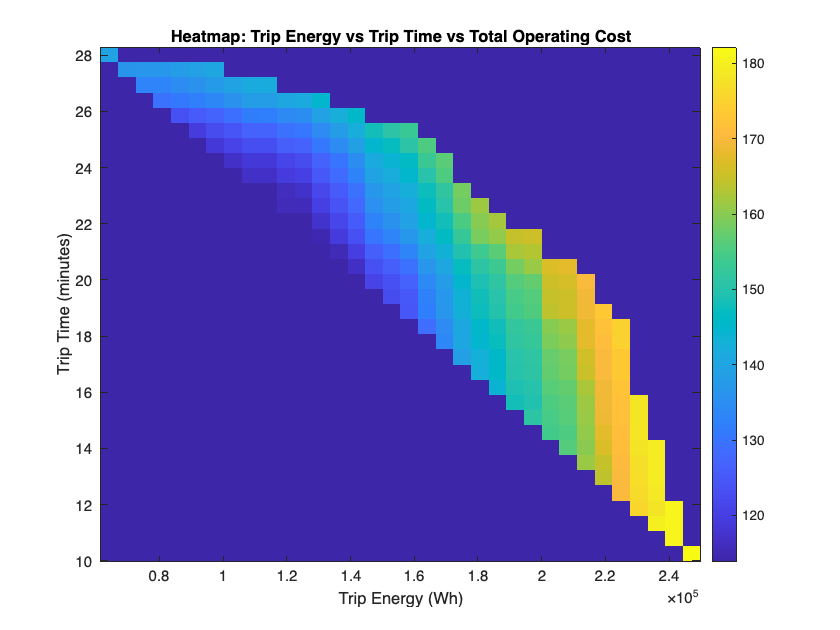


% Creating the heatmap with swapped axes
figure;
imagesc(TripEnergy(1,:), trip_time_minutes, TotalOperatingCost);
set(gca, 'YDir', 'normal'); % Ensures that the Y-axis values are in the correct order
title('Heatmap: Trip Energy vs Trip Time vs Total Operating Cost');
xlabel('Trip Energy (Wh)');
ylabel('Trip Time (minutes)');
colorbar; % Adds a color bar to indicate cost levels

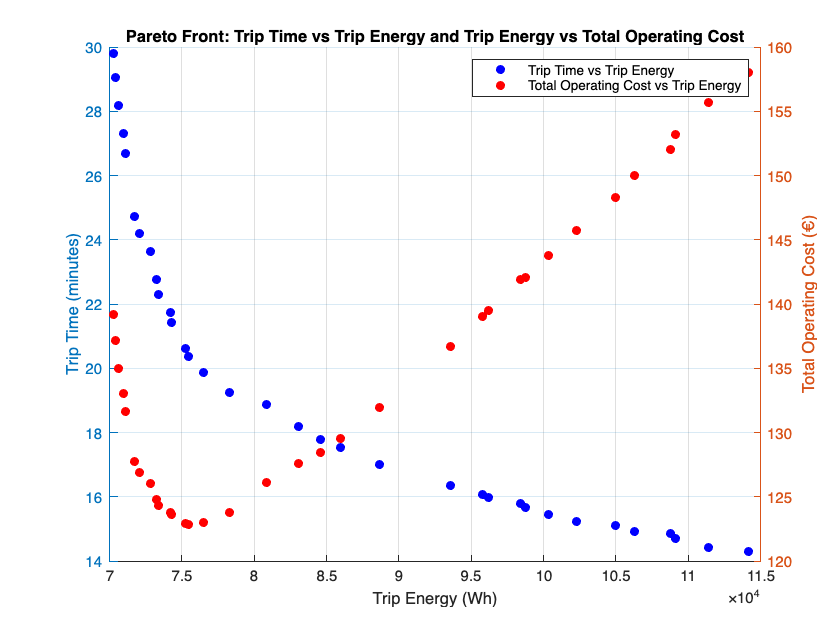








%%%%%%% Double Grpah - PARETO + TOC

% Create a figure
figure;

% Plot the first curve: Trip Time vs Trip Energy on the left y-axis
yyaxis left;
scatter(trip_energy, trip_time/60, 'filled', 'b');
ylabel('Trip Time (minutes)'); % Label for the left y-axis
xlabel('Trip Energy (Wh)'); % Label for the x-axis
grid on; % Add grid for better readability

% Plot the second curve: Total Operating Cost vs Trip Energy on the right y-axis
yyaxis right;
scatter(trip_energy, toc_values, 'filled', 'r');
ylabel('Total Operating Cost (€)'); % Label for the right y-axis

% Add a title and customize the appearance
title('Pareto Front: Trip Time vs Trip Energy and Trip Energy vs Total Operating Cost');
legend('Trip Time vs Trip Energy', 'Total Operating Cost vs Trip Energy');

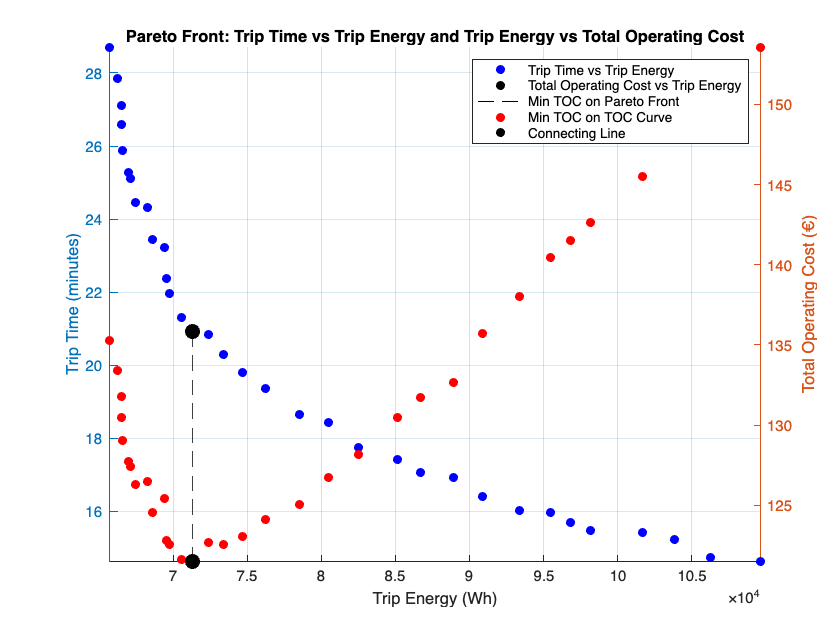


% Optionally, you can adjust the limits of the axes if needed
% xlim([min(trip_energy) max(trip_energy)]);
% ylim left; % For the left y-axis
% ylim right; % For the right y-axis








%%%%%%% Double Grpah - PARETO + TOC with LINE

% Assuming 'toc_values', 'trip_time', and 'trip_energy' are already defined

% Find the index of the minimum TOC
[~, minTocIndex] = min(toc_values);
minTocEnergy = trip_energy(minTocIndex);
minTocTime = trip_time(minTocIndex)/60;  % Convert to minutes
minTocValue = toc_values(minTocIndex);

% Create a figure
figure;

% Plot the first curve: Trip Time vs Trip Energy on the left y-axis
yyaxis left;
scatter(trip_energy, trip_time/60, 'filled', 'b');
ylabel('Trip Time (minutes)'); % Label for the left y-axis
xlabel('Trip Energy (Wh)'); % Label for the x-axis
grid on; % Add grid for better readability

% Highlight the point on the Pareto front with the minimum TOC
hold on;
scatter(minTocEnergy, minTocTime, 100, 'k', 'filled'); % Highlighted point in black
line([minTocEnergy minTocEnergy], [minTocTime 0], 'Color', 'k', 'LineStyle', '--'); % Line to the x-axis

% Plot the second curve: Total Operating Cost vs Trip Energy on the right y-axis
yyaxis right;
scatter(trip_energy, toc_values, 'filled', 'r');
ylabel('Total Operating Cost (€)'); % Label for the right y-axis

% Highlight the point on the TOC plot
hold on;
scatter(minTocEnergy, minTocValue, 100, 'k', 'filled'); % Highlighted point in black
line([minTocEnergy minTocEnergy], [minTocValue 0], 'Color', 'k', 'LineStyle', '--'); % Line to the x-axis

% Draw a line connecting the two highlighted points
line([minTocEnergy minTocEnergy], [minTocTime minTocValue], 'Color', 'g', 'LineWidth', 2); % Green line connecting points

% Adjust axis limits for better scalability
yyaxis left;
xlim([min(trip_energy) max(trip_energy)]);  % Adjust X-axis limits
ylim([min(trip_time/60) max(trip_time/60)]); % Adjust left Y-axis limits

yyaxis right;
ylim([min(toc_values) max(toc_values)]);  % Adjust right Y-axis limits

% Add a title and customize the appearance
title('Pareto Front: Trip Time vs Trip Energy and Trip Energy vs Total Operating Cost');
legend('Trip Time vs Trip Energy', 'Total Operating Cost vs Trip Energy', 'Min TOC on Pareto Front', 'Min TOC on TOC Curve', 'Connecting Line');

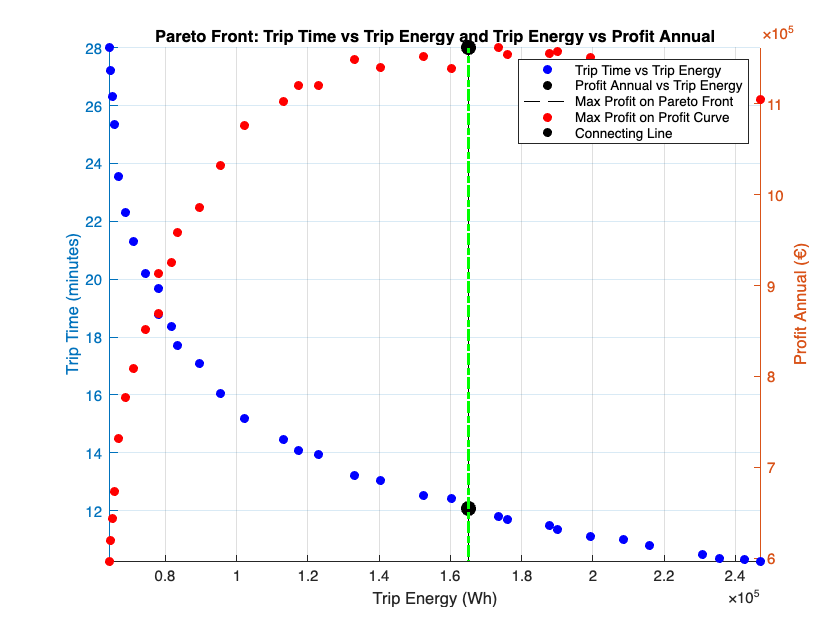




% Find the index of the maximum annual Profit 
[~, minProfitIndex] = max(Profit_annual);
minProfitEnergy = trip_energy(minProfitIndex);
minProfitTime = trip_time(minProfitIndex)/60;  % Convert to minutes
minProfitValue = Profit_annual(minProfitIndex);

% Create a figure
figure;

% Plot the first curve: Trip Time vs Trip Energy on the left y-axis
yyaxis left;
scatter(trip_energy, trip_time/60, 'filled', 'b');
ylabel('Trip Time (minutes)'); % Label for the left y-axis
xlabel('Trip Energy (Wh)'); % Label for the x-axis
grid on; % Add grid for better readability

% Highlight the point on the Pareto front with the minimum GWP_annual
hold on;
scatter(minProfitEnergy, minProfitTime, 100, 'k', 'filled'); % Highlighted point in black
line([minProfitEnergy minProfitEnergy], [minProfitTime 0], 'Color', 'k', 'LineStyle', '--'); % Line to the x-axis

% Plot the second curve: GWP_annual vs Trip Energy on the right y-axis
yyaxis right;
scatter(trip_energy, Profit_annual, 'filled', 'r');
ylabel('Profit Annual (€)'); % Label for the right y-axis

% Highlight the point on the GWP_annual plot
hold on;
scatter(minProfitEnergy, minProfitValue, 100, 'k', 'filled'); % Highlighted point in black
line([minProfitEnergy minProfitEnergy], [minProfitValue 0], 'Color', 'k', 'LineStyle', '--'); % Line to the x-axis

% Draw a line connecting the two highlighted points
line([minProfitEnergy minProfitEnergy], [minProfitTime minProfitValue], 'Color', 'g', 'LineWidth', 2); % Green line connecting points

% Adjust axis limits for better scalability
yyaxis left;
xlim([min(trip_energy) max(trip_energy)]);  % Adjust X-axis limits
ylim([min(trip_time/60) max(trip_time/60)]); % Adjust left Y-axis limits

yyaxis right;
ylim([min(Profit_annual) max(Profit_annual)]);  % Adjust right Y-axis limits

% Add a title and customize the appearance
title('Pareto Front: Trip Time vs Trip Energy and Trip Energy vs Profit Annual');
legend('Trip Time vs Trip Energy', 'Profit Annual vs Trip Energy', 'Max Profit on Pareto Front', 'Max Profit on Profit Curve', 'Connecting Line');

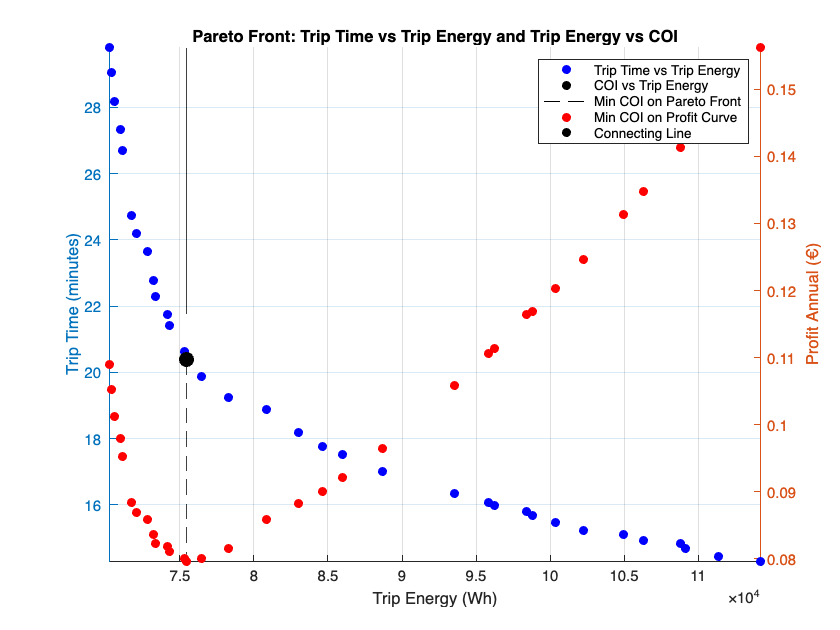








% Find the index of the minimum COI
[~, minCOIIndex] = min(COI_values);
minCOIEnergy = trip_energy(minCOIIndex);
minCOITime = trip_time(minCOIIndex)/60;  % Convert to minutes
minCOIValue = Profit_annual(minCOIIndex);

% Create a figure
figure;

% Plot the first curve: Trip Time vs Trip Energy on the left y-axis
yyaxis left;
scatter(trip_energy, trip_time/60, 'filled', 'b');
ylabel('Trip Time (minutes)'); % Label for the left y-axis
xlabel('Trip Energy (Wh)'); % Label for the x-axis
grid on; % Add grid for better readability

% Highlight the point on the Pareto front with the minimum GWP_annual
hold on;
scatter(minCOIEnergy, minCOITime, 100, 'k', 'filled'); % Highlighted point in black
line([minCOIEnergy minCOIEnergy], [minCOITime 0], 'Color', 'k', 'LineStyle', '--'); % Line to the x-axis

% Plot the second curve: GWP_annual vs Trip Energy on the right y-axis
yyaxis right;
scatter(trip_energy, COI_values, 'filled', 'r');
ylabel('Profit Annual (€)'); % Label for the right y-axis

% Highlight the point on the GWP_annual plot
hold on;
scatter(minCOIEnergy, minCOIValue, 100, 'k', 'filled'); % Highlighted point in black
line([minCOIEnergy minCOIEnergy], [minCOIValue 0], 'Color', 'k', 'LineStyle', '--'); % Line to the x-axis

% Draw a line connecting the two highlighted points
line([minCOIEnergy minCOIEnergy], [minCOITime minCOIValue], 'Color', 'g', 'LineWidth', 2); % Green line connecting points

% Adjust axis limits for better scalability
yyaxis left;
xlim([min(trip_energy) max(trip_energy)]);  % Adjust X-axis limits
ylim([min(trip_time/60) max(trip_time/60)]); % Adjust left Y-axis limits

yyaxis right;
ylim([min(COI_values) max(COI_values)]);  % Adjust right Y-axis limits

% Add a title and customize the appearance
title('Pareto Front: Trip Time vs Trip Energy and Trip Energy vs COI');
legend('Trip Time vs Trip Energy', 'COI vs Trip Energy', 'Min COI on Pareto Front', 'Min COI on Profit Curve', 'Connecting Line');

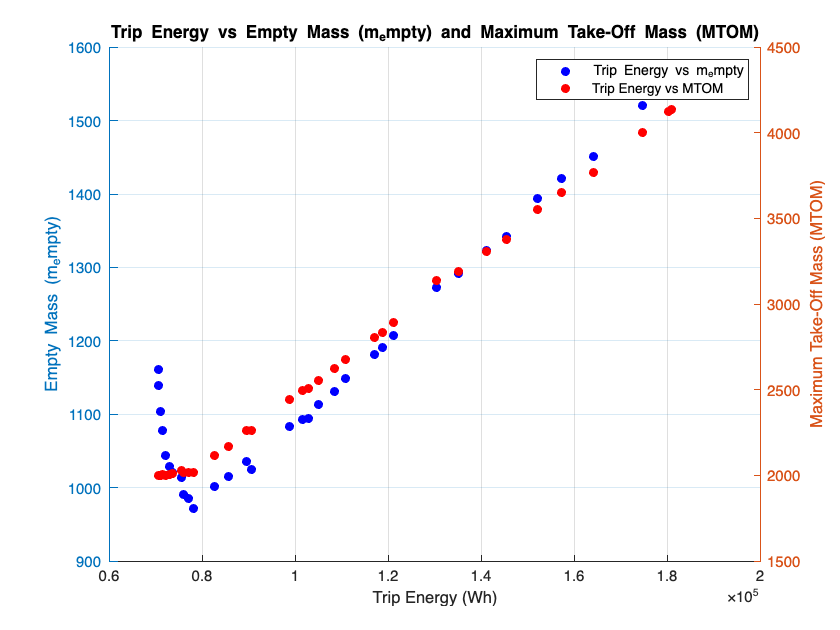






%%%%%%%%% MTOM and M_empty Graph 

% Extract the necessary data from the sortedResultsTable
trip_energy = sortedResultsTable{:, 'Trip_Energy [Wh]'};
m_empty = sortedResultsTable{:, 'm_empty [kg]'};
MTOM = sortedResultsTable{:, 'MTOM [kg]'};

% Create a figure
figure;

% Plot the first curve: Trip Energy vs m_empty on the left y-axis
yyaxis left;
scatter(trip_energy, m_empty, 'filled', 'b');
ylabel('Empty Mass (m_empty)'); % Label for the left y-axis
xlabel('Trip Energy (Wh)'); % Label for the x-axis
grid on; % Add grid for better readability

% Plot the second curve: Trip Energy vs MTOM on the right y-axis
yyaxis right;
scatter(trip_energy, MTOM, 'filled', 'r');
ylabel('Maximum Take-Off Mass (MTOM)'); % Label for the right y-axis

% Add a title and customize the appearance
title('Trip Energy vs Empty Mass (m_empty) and Maximum Take-Off Mass (MTOM)');
legend('Trip Energy vs m_empty', 'Trip Energy vs MTOM');


% Optionally, you can adjust the limits of the axes if needed
% xlim([min(trip_energy) max(trip_energy)]);
% ylim left; % For the left y-axis
% ylim right; % For the right y-axis








## Extracting the Analysis Data for Post-Analysis:

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Specify the full directory path where you want to save the files
saveDir = '/Users/johannes/Dropbox/Mein Mac (Johanness MacBook Pro (2))/Documents/MATLAB/Master_Project/MDO_MOO_Model_v5_080824/Matlab_Files_PostProcessing';

% Check if the directory exists, and if not, create it
if ~exist(saveDir, 'dir')
    mkdir(saveDir);
end

% Example: Saving optimization results for a scenario and a macro scenario
macroScenario = '70km'; % Example for the macro scenario
scenarioNumber = 5; % For example, for Scenario K01

% Example: Adding scenario and macro scenario identifiers to each row

% Add a new column for macro scenario and scenario number
minERow.Scenario = repmat({sprintf('K%02d', scenarioNumber)}, height(minERow), 1);
minERow.MacroScenario = repmat({macroScenario}, height(minERow), 1);

minGWPFRow.Scenario = repmat({sprintf('K%02d', scenarioNumber)}, height(minGWPFRow), 1);
minGWPFRow.MacroScenario = repmat({macroScenario}, height(minGWPFRow), 1);

minGWPaRow.Scenario = repmat({sprintf('K%02d', scenarioNumber)}, height(minGWPaRow), 1);
minGWPaRow.MacroScenario = repmat({macroScenario}, height(minGWPaRow), 1);

minTocRow.Scenario = repmat({sprintf('K%02d', scenarioNumber)}, height(minTocRow), 1);
minTocRow.MacroScenario = repmat({macroScenario}, height(minTocRow), 1);

maxProfitFRow.Scenario = repmat({sprintf('K%02d', scenarioNumber)}, height(maxProfitFRow), 1);
maxProfitFRow.MacroScenario = repmat({macroScenario}, height(maxProfitFRow), 1);

maxProfitaRow.Scenario = repmat({sprintf('K%02d', scenarioNumber)}, height(maxProfitaRow), 1);
maxProfitaRow.MacroScenario = repmat({macroScenario}, height(maxProfitaRow), 1);

maxFOMRow.Scenario = repmat({sprintf('K%02d', scenarioNumber)}, height(maxFOMRow), 1);
maxFOMRow.MacroScenario = repmat({macroScenario}, height(maxFOMRow), 1);

minCOIRow.Scenario = repmat({sprintf('K%02d', scenarioNumber)}, height(minCOIRow), 1);
minCOIRow.MacroScenario = repmat({macroScenario}, height(minCOIRow), 1);

minCSIRow.Scenario = repmat({sprintf('K%02d', scenarioNumber)}, height(minCSIRow), 1);
minCSIRow.MacroScenario = repmat({macroScenario}, height(minCSIRow), 1);


% Save results in a structure
resultsStruct = struct();
resultsStruct.minERow = minERow;
resultsStruct.minGWPFRow = minGWPFRow;
resultsStruct.minGWPaRow = minGWPaRow;
resultsStruct.minTocRow = minTocRow;
resultsStruct.maxProfitFRow = maxProfitFRow;
resultsStruct.maxProfitaRow = maxProfitaRow;
resultsStruct.maxFOMRow = maxFOMRow;
resultsStruct.minCOIRow = minCOIRow;
resultsStruct.minCSIRow = minCSIRow;

% Create the full file path for the .mat file
matFilename = sprintf('scenario_K%02d_%s_results.mat', scenarioNumber, macroScenario);
fullMatFilePath = fullfile(saveDir, matFilename);

% Save the structure in the specified directory as a .mat file
save(fullMatFilePath, 'resultsStruct');

% Create the full file path for the Excel file
excelFilename = sprintf('scenario_K%02d_%s_results.xlsx', scenarioNumber, macroScenario);
fullExcelFilePath = fullfile(saveDir, excelFilename);

% Save the sorted results table in the first sheet of the Excel file
writetable(sortedResultsTable, fullExcelFilePath, 'Sheet', 'Sorted_Results');

% Save each of the other tables as separate sheets in the Excel file
writetable(minERow, fullExcelFilePath, 'Sheet', 'Min_Energy');
writetable(minGWPFRow, fullExcelFilePath, 'Sheet', 'Min_GWP_Flight');
writetable(minGWPaRow, fullExcelFilePath, 'Sheet', 'Min_GWP_Annual');
writetable(minTocRow, fullExcelFilePath, 'Sheet', 'Min_TOC');
writetable(maxProfitFRow, fullExcelFilePath, 'Sheet', 'Max_Profit_Flight');
writetable(maxProfitaRow, fullExcelFilePath, 'Sheet', 'Max_Profit_Annual');
writetable(maxFOMRow, fullExcelFilePath, 'Sheet', 'Max_FOM');
writetable(minCOIRow, fullExcelFilePath, 'Sheet', 'Min_COI');
writetable(minCSIRow, fullExcelFilePath, 'Sheet', 'Min_CSI');

## Extracting highest eVTOL-FoM for Intermodal Comparison:


% to extract the eVTOL configuration with the maximum FoM
[maxFoM, maxIndex] = max(resultsTable{:, 'eVTOL_FoM [-]'});
bestConfig = resultsTable(maxIndex, :);

% Calling the function to calculate FoM for all transportation modes
FoM_results = calculateTransportationFoMx(bestConfig, params, set_trip_distance);

Intermediate Values in calculateTransportationFoM:
time_rating: 10
co2_rating: 6.8019
energy_rating: 6.3789
costs_rating: 2.3206
FoM: 6.3753



% to display the results
disp(FoM_results);

               Mode                TimeDemand    TimeRating    CO2_total    CO2Rating    EnergyTotal    EnergyRating    CostsTotal    CostsRating     FoM  
    ___________________________    __________    __________    _________    _________    ___________    ____________    __________    ___________    ______

    {'Electric Vehicle (5)'   }      64.235         8.569        1.183       9.4182         3143.1         8.2536          1.911        5.2266       7.8668
    {'Bicycle'                }      285.96             1            0           10        -9955.5             10        -43.994            10         7.75
    {'Train (100%)'           }    

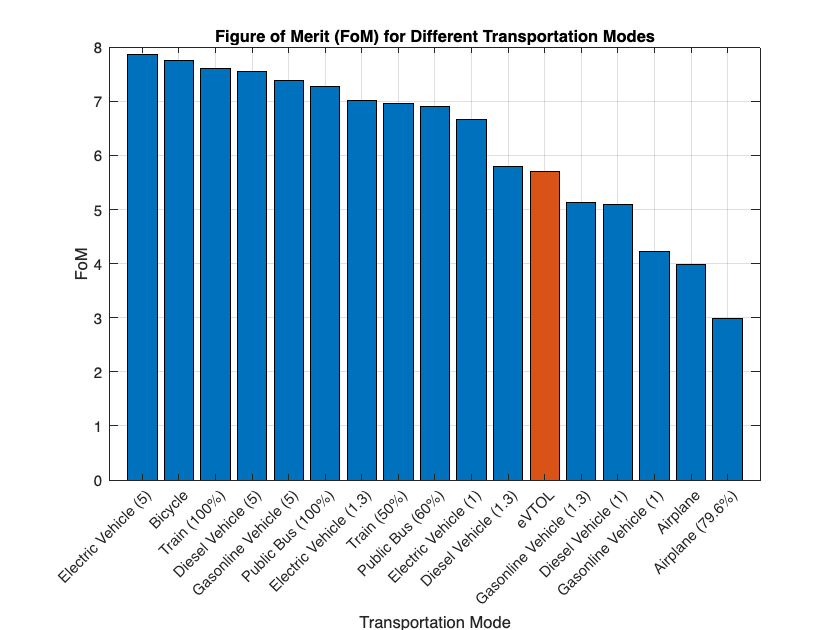


% to ensure the categories are ordered as per the sorted results
mode_categories = categorical(FoM_results.Mode);
mode_categories = reordercats(mode_categories, FoM_results.Mode);

% to identify the index of the eVTOL mode in the sorted results
eVTOL_index = find(FoM_results.Mode == "eVTOL");

% Plotting the results in descending order
figure;
b = bar(mode_categories, FoM_results.FoM);
title('Figure of Merit (FoM) for Different Transportation Modes');
xlabel('Transportation Mode');
ylabel('FoM');
set(gca, 'XTickLabelRotation', 45); % Rotating x-axis labels for better readability
grid on;

% to change the color of the eVTOL bar to orange
b.FaceColor = 'flat';
colors = repmat([0 0.4470 0.7410], length(FoM_results.FoM), 1); % Default blue color for all bars
colors(eVTOL_index, :) = [0.8500 0.3250 0.0980]; % Orange color for eVTOL
b.CData = colors;

## Validation Sequence

% calculate the validation model with best configuration

% Recheck the highest FoM design
validationResults = recheckModel1(bestConfig{:, 'rho_bat [Wh/kg]'}, bestConfig{:, 'MTOM [kg]'}, bestConfig{:, 'm_furnish [kg]'}, bestConfig{:, 'm_fuselage [kg]'}, bestConfig{:, 'm_system [kg]'}, bestConfig{:, 'm_wing [kg]'}, bestConfig{:, 'm_rotor [kg]'}, bestConfig{:, 'm_motor [kg]'}, bestConfig{:, 'm_bat [kg]'}, bestConfig{:, 'm_gear [kg]'}, bestConfig{:, 'chord [m]'}, bestConfig{:, 'wingspan_b [m]'}, bestConfig{:, 'V_cruise [m/s]'}, bestConfig{:, 'V_climb [m/s]'}, bestConfig{:, 'R_cruise [m]'}, bestConfig{:, 'R_hover [m]'}, set_trip_distance, params);

% Extract best configuration values
bestConfigValues = struct(   'Trip_Energy', bestConfig{:, 'Trip_Energy [Wh]'}, ...
    'Trip_Time', bestConfig{:, 'Trip_Time [sec]'}, ...
    'MTOM', bestConfig{:, 'MTOM [kg]'}, ...
    'R_cruise', bestConfig{:, 'R_cruise [m]'}, ...
    'R_hover', bestConfig{:, 'R_hover [m]'}, ...
    'chord', bestConfig{:, 'chord [m]'}, ...
    'wingspan_b', bestConfig{:, 'wingspan_b [m]'}, ...
    'rho_bat', bestConfig{:, 'rho_bat [Wh/kg]'}, ...
    'V_cruise', bestConfig{:, 'V_cruise [m/s]'}, ...
    'V_climb', bestConfig{:, 'V_climb [m/s]'}, ...
    'Power_Hover', bestConfig{:, 'Power_hover [W]'}, ...
    'Power_Climb', bestConfig{:, 'Power_climb [W]'}, ...
    'Power_Cruise', bestConfig{:, 'Power_cruise [W]'}, ...
    'm_empty', bestConfig{:, 'm_empty [kg]'}, ...
    'm_pay', bestConfig{:, 'm_pay [kg]'}, ...
    'm_bat', bestConfig{:, 'm_bat [kg]'}, ...
    'm_motor', bestConfig{:, 'm_motor [kg]'}, ...
    'm_rotor', bestConfig{:, 'm_rotor [kg]'}, ...
    'm_wing', bestConfig{:, 'm_wing [kg]'}, ...
    'm_gear', bestConfig{:, 'm_gear [kg]'}, ...
    'm_furnish', bestConfig{:, 'm_furnish [kg]'}, ...
    'm_fuselage', bestConfig{:, 'm_fuselage [kg]'}, ...
    'm_system', bestConfig{:, 'm_system [kg]'}, ...
    'c_l_cruise', bestConfig{:, 'c_l_cruise [-]'}, ...
    'c_l_climb', bestConfig{:, 'c_l_climb [-]'}, ...
    'c_d_cruise', bestConfig{:, 'c_d_cruise [-]'}, ...
    'c_d_climb', bestConfig{:, 'c_d_climb [-]'}, ...
    'toc_s', bestConfig{:, 'TOC_skm [€/skm]'}, ...
    'toc', bestConfig{:, 'TOC [€]'}, ...
    'coc', bestConfig{:, 'COC [€]'}, ...
    'c_e', bestConfig{:, 'C_energy [€]'}, ...
    'c_m', bestConfig{:, 'C_m [€]'}, ...
    'c_mwr', bestConfig{:, 'C_mwr [€]'}, ...
    'c_mb', bestConfig{:, 'C_mb [€]'}, ...
    'c_n', bestConfig{:, 'C_nav [€]'}, ...
    'c_cob', bestConfig{:, 'C_crew [€]'}, ...
    'coo', bestConfig{:, 'COO [€]'}, ...
    'ioc', bestConfig{:, 'IOC [€]'}, ...
    'n_bat_req', bestConfig{:, 'n_bat_req_a [-]'}, ...
    'P_bat_single', bestConfig{:, 'P_bat_single [€]'}, ...
    'P_bat_annual', bestConfig{:, 'P_bat_annual [€]'}, ...
    'FC_a', bestConfig{:, 'FC_a [-]'}, ...
    'FC_d', bestConfig{:, 'FC_d [-]'}, ...
    'd_cru', bestConfig{:, 'd_cru [m]'}, ...
    'd_cl', bestConfig{:, 'd_cl [m]'});

% Calculate relative differences
fields = fieldnames(bestConfigValues);
relativeDifference = struct();

for i = 1:numel(fields)
    field = fields{i};
    relativeDifference.(field) = round((validationResults.(field) - bestConfigValues.(field)) / bestConfigValues.(field) * 100, 2);
end

% Create the comparison table
comparisonTable = table(struct2array(bestConfigValues)', struct2array(validationResults)', struct2array(relativeDifference)', ...
                        'VariableNames', {'BestConfig', 'Recheck', 'RelativeDifference(%)'}, ...
                        'RowNames', fields);


% Saving the table to an Excel file
writetable(comparisonTable, 'halfdesign_results_v5.xlsx');

% Display the comparison table
disp('Comparison Table:');

Comparison Table:


disp(comparisonTable);

                    BestConfig     Recheck      RelativeDifference(%)
                    __________    __________    _____________________

    Trip_Energy          68818         27118           -60.59        
    Trip_Time           1338.9         360.8           -73.05        
    MTOM                1913.5        1913.5                0        
    R_cruise            1.8375        1.8375                0        
    R_hover             1.3844        1.3844                0        
    chord               1.3062        1.3062                0        
    wingspan_b          15.842        15.842                0        
    rho_bat                400           400                0        
    V_cruise            57.253        57.253


constraint_cruise = bestConfig{:, 'MTOM [kg]'} * params.g - ...
    params.rho/2 * bestConfig{:, 'V_cruise [m/s]'}^2 * ...
    bestConfig{:, 'chord [m]'} * bestConfig{:, 'wingspan_b [m]'} * ...
    bestConfig{:, 'c_l_cruise [-]'};

cruise_requirement = sqrt(bestConfig{:, 'MTOM [kg]'} * params.g * 2 / ...
    (params.rho * bestConfig{:, 'chord [m]'} * ...
    bestConfig{:, 'wingspan_b [m]'} * bestConfig{:, 'c_l_cruise [-]'}));

climb_requirement = sqrt(cosd(params.alpha_deg_climb) * ...
    bestConfig{:, 'MTOM [kg]'} * params.g * 2 / ...
    (params.rho_climb * bestConfig{:, 'c_l_climb [-]'} * ...
    bestConfig{:, 'chord [m]'} * bestConfig{:, 'wingspan_b [m]'}));

disp('Cruise Condition Check:');

Cruise Condition Check:


disp(constraint_cruise);

   3.6380e-12




disp('Cruise Speed Required:');

Cruise Speed Required:


disp(cruise_requirement);

   57.2534




disp('Climb Speed Required:');

Climb Speed Required:


disp(climb_requirement);

   40.1849





disp('(1) MTOM Penalty:');

(1) MTOM Penalty:


disp(constraint_cruise/9.81);

   3.7084e-13




disp('(2) Climb Speed Penalty:');

(2) Climb Speed Penalty:


disp(climb_requirement- bestConfig{:, 'V_climb [m/s]'});

   -1.4218




disp('(3) Cruise Speed Penalty:');

(3) Cruise Speed Penalty:


disp(cruise_requirement - bestConfig{:, 'V_cruise [m/s]'});

     0





% compare values in total as well relative in a table

% idea: recirculat the whole optimization until the validation discrepancy
% is wihtin a defined margin 



% Fastest Solution:

% to extract the eVTOL configuration with the minimum FoM
[minFoM, minIndex] = min(resultsTable{:, 'eVTOL_FoM [-]'});
worstConfig = resultsTable(minIndex, :);

% Calling the function to calculate FoM for all transportation modes
FoM_results_worst = calculateTransportationFoMx(worstConfig, params, set_trip_distance);

Intermediate Values in calculateTransportationFoM:
time_rating: 10
co2_rating: 1
energy_rating: 1
costs_rating: 1
FoM: 3.25



% to display the results
disp(FoM_results_worst);

               Mode                TimeDemand    TimeRating    CO2_total    CO2Rating    EnergyTotal    EnergyRating    CostsTotal    CostsRating     FoM  
    ___________________________    __________    __________    _________    _________    ___________    ____________    __________    ___________    ______

    {'Electric Vehicle (5)'   }      64.235         8.238        1.183        9.544         3143.1         8.3564          1.911        5.3853       7.8809
    {'Bicycle'                }      285.96             1            0           10        -9955.5             10        -43.994            10         7.75
    {'Train (100%)'           }    

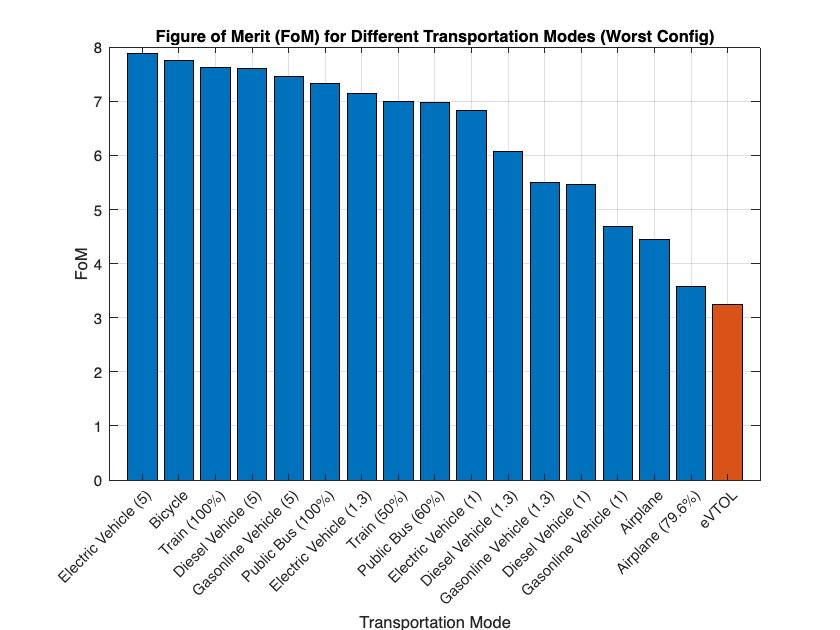


% to ensure the categories are ordered as per the sorted results
mode_categories_worst = categorical(FoM_results_worst.Mode);
mode_categories_worst = reordercats(mode_categories_worst, FoM_results_worst.Mode);

% to identify the index of the eVTOL mode in the sorted results
eVTOL_index_worst = find(FoM_results_worst.Mode == "eVTOL");

% Plotting the results in descending order
figure;
b_worst = bar(mode_categories_worst, FoM_results_worst.FoM);
title('Figure of Merit (FoM) for Different Transportation Modes (Worst Config)');
xlabel('Transportation Mode');
ylabel('FoM');
set(gca, 'XTickLabelRotation', 45); % Rotating x-axis labels for better readability
grid on;

% to change the color of the eVTOL bar to orange
b_worst.FaceColor = 'flat';
colors_worst = repmat([0 0.4470 0.7410], length(FoM_results_worst.FoM), 1); % Default blue color for all bars
colors_worst(eVTOL_index_worst, :) = [0.8500 0.3250 0.0980]; % Orange color for eVTOL
b_worst.CData = colors_worst;



% Recheck the worst FoM design
validationResultsWorst = recheckModel1( ...
    worstConfig{:, 'rho_bat [Wh/kg]'}, ...
    worstConfig{:, 'MTOM [kg]'}, ...
    bestConfig{:, 'm_furnish [kg]'}, ...
    worstConfig{:, 'm_fuselage [kg]'}, ...
    worstConfig{:, 'm_system [kg]'}, ...
    worstConfig{:, 'm_wing [kg]'}, ...
    worstConfig{:, 'm_rotor [kg]'}, ...
    worstConfig{:, 'm_motor [kg]'}, ...
    worstConfig{:, 'm_bat [kg]'}, ...
    worstConfig{:, 'm_gear [kg]'}, ...
    worstConfig{:, 'chord [m]'}, ...
    worstConfig{:, 'wingspan_b [m]'}, ...
    worstConfig{:, 'V_cruise [m/s]'}, ...
    worstConfig{:, 'V_climb [m/s]'}, ...
    worstConfig{:, 'R_cruise [m]'}, ...
    worstConfig{:, 'R_hover [m]'}, ...
    set_trip_distance, params);

% Extract worst configuration values
worstConfigValues = struct('Trip_Energy', worstConfig{:, 'Trip_Energy [Wh]'}, ...
    'Trip_Time', worstConfig{:, 'Trip_Time [sec]'}, ...
    'MTOM', worstConfig{:, 'MTOM [kg]'}, ...
    'R_cruise', worstConfig{:, 'R_cruise [m]'}, ...
    'R_hover', worstConfig{:, 'R_hover [m]'}, ...
    'chord', worstConfig{:, 'chord [m]'}, ...
    'wingspan_b', worstConfig{:, 'wingspan_b [m]'}, ...
    'rho_bat', worstConfig{:, 'rho_bat [Wh/kg]'}, ...
    'V_cruise', worstConfig{:, 'V_cruise [m/s]'}, ...
    'V_climb', worstConfig{:, 'V_climb [m/s]'}, ...
    'Power_Hover', worstConfig{:, 'Power_hover [W]'}, ...
    'Power_Climb', worstConfig{:, 'Power_climb [W]'}, ...
    'Power_Cruise', worstConfig{:, 'Power_cruise [W]'}, ...
    'm_empty', worstConfig{:, 'm_empty [kg]'}, ...
    'm_pay', worstConfig{:, 'm_pay [kg]'}, ...
    'm_bat', worstConfig{:, 'm_bat [kg]'}, ...
    'm_motor', worstConfig{:, 'm_motor [kg]'}, ...
    'm_rotor', worstConfig{:, 'm_rotor [kg]'}, ...
    'm_wing', worstConfig{:, 'm_wing [kg]'}, ...
    'm_gear', worstConfig{:, 'm_gear [kg]'}, ...
    'm_furnish', worstConfig{:, 'm_furnish [kg]'}, ...
    'm_fuselage', worstConfig{:, 'm_fuselage [kg]'}, ...
    'm_system', worstConfig{:, 'm_system [kg]'}, ...
    'c_l_cruise', worstConfig{:, 'c_l_cruise [-]'}, ...
    'c_l_climb', worstConfig{:, 'c_l_climb [-]'}, ...
    'c_d_cruise', worstConfig{:, 'c_d_cruise [-]'}, ...
    'c_d_climb', worstConfig{:, 'c_d_climb [-]'}, ...
    'toc_s', worstConfig{:, 'TOC_skm [€/skm]'}, ...
    'toc', worstConfig{:, 'TOC [€]'}, ...
    'coc', worstConfig{:, 'COC [€]'}, ...
    'c_e', worstConfig{:, 'C_energy [€]'}, ...
    'c_m', worstConfig{:, 'C_m [€]'}, ...
    'c_mwr', worstConfig{:, 'C_mwr [€]'}, ...
    'c_mb', worstConfig{:, 'C_mb [€]'}, ...
    'c_n', worstConfig{:, 'C_nav [€]'}, ...
    'c_cob', worstConfig{:, 'C_crew [€]'}, ...
    'coo', worstConfig{:, 'COO [€]'}, ...
    'ioc', worstConfig{:, 'IOC [€]'}, ...
    'n_bat_req', worstConfig{:, 'n_bat_req_a [-]'}, ...
    'P_bat_single', worstConfig{:, 'P_bat_single [€]'}, ...
    'P_bat_annual', worstConfig{:, 'P_bat_annual [€]'}, ...
    'FC_a', worstConfig{:, 'FC_a [-]'}, ...
    'FC_d', worstConfig{:, 'FC_d [-]'}, ...
    'd_cru', worstConfig{:, 'd_cru [m]'}, ...
    'd_cl', worstConfig{:, 'd_cl [m]'});

% Calculate relative differences for the worst configuration
relativeDifferenceWorst = struct();

for i = 1:numel(fields)
    field = fields{i};
    relativeDifferenceWorst.(field) = round((validationResultsWorst.(field) - worstConfigValues.(field)) / worstConfigValues.(field) * 100, 2);
end

% Create the comparison table for the worst configuration
comparisonTableWorst = table(struct2array(worstConfigValues)', struct2array(validationResultsWorst)', struct2array(relativeDifferenceWorst)', ...
                             'VariableNames', {'WorstConfig', 'Recheck', 'RelativeDifference(%)'}, ...
                             'RowNames', fields);

% Display the comparison table for the worst configuration
disp('Comparison Table (Worst Config):');

Comparison Table (Worst Config):


disp(comparisonTableWorst);

                    WorstConfig     Recheck      RelativeDifference(%)
                    ___________    __________    _____________________

    Trip_Energy     2.4707e+05     1.0359e+05           -58.08        
    Trip_Time           615.63         189.85           -69.16        
    MTOM                5613.4         5613.4                0        
    R_cruise            1.2969         1.2969                0        
    R_hover             1.2811         1.2811                0        
    chord                  1.3            1.3                0        
    wingspan_b          9.3729         9.3729                0        
    rho_bat                400            400                0        
    V_cruise            131.52    


constraint_cruise_worst = worstConfig{:, 'MTOM [kg]'} * params.g - ...
    params.rho/2 * worstConfig{:, 'V_cruise [m/s]'}^2 * ...
    worstConfig{:, 'chord [m]'} * worstConfig{:, 'wingspan_b [m]'} * ...
    worstConfig{:, 'c_l_cruise [-]'};

cruise_requirement_worst = sqrt(worstConfig{:, 'MTOM [kg]'} * params.g * 2 / ...
    (params.rho * worstConfig{:, 'chord [m]'} * ...
    worstConfig{:, 'wingspan_b [m]'} * worstConfig{:, 'c_l_cruise [-]'}));

climb_requirement_worst = sqrt(cosd(params.alpha_deg_climb) * ...
    worstConfig{:, 'MTOM [kg]'} * params.g * 2 / ...
    (params.rho_climb * worstConfig{:, 'c_l_climb [-]'} * ...
    worstConfig{:, 'chord [m]'} * worstConfig{:, 'wingspan_b [m]'}));

disp('Cruise Condition Check (Worst Config):');

Cruise Condition Check (Worst Config):


disp(constraint_cruise_worst);

   7.2760e-12




disp('Cruise Speed Required (Worst Config):');

Cruise Speed Required (Worst Config):


disp(cruise_requirement_worst);

  131.5237




disp('Climb Speed Required (Worst Config):');

Climb Speed Required (Worst Config):


disp(climb_requirement_worst);

   93.4519




disp('(1) MTOM Penalty (Worst Config):');

(1) MTOM Penalty (Worst Config):


disp(constraint_cruise_worst / 9.81);

   7.4169e-13




disp('(2) Climb Speed Penalty (Worst Config):');

(2) Climb Speed Penalty (Worst Config):


disp(climb_requirement_worst - worstConfig{:, 'V_climb [m/s]'});

   -3.3064




disp('(3) Cruise Speed Penalty (Worst Config):');

(3) Cruise Speed Penalty (Worst Config):


disp(cruise_requirement_worst - worstConfig{:, 'V_cruise [m/s]'});

     0



Drawing the eVTOL Configruation (against the baseline configuration)

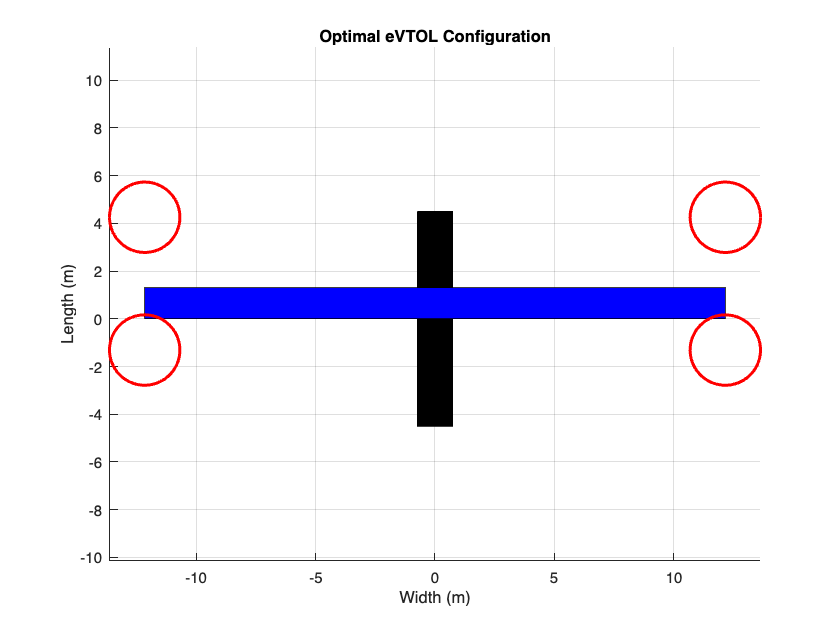

% Under construction 

% Extract the optimal parameters from the best configuration
bestConfig = sortedResultsTable(1, :);

R_prop_hover = bestConfig{:, 'R_hover [m]'};
R_prop_cruise = bestConfig{:, 'R_cruise [m]'};
wingspan = bestConfig{:, 'wingspan_b [m]'};
chord = bestConfig{:, 'chord [m]'};

% Call the function to draw the eVTOL
drawEVTOL(R_prop_hover, R_prop_cruise, wingspan, chord, 'Optimal eVTOL Configuration');